# ECM307-G01T02L03D - Atividade T3

%% Atividade T3 - Análise de Vogais
%% Luis Guilherme de Souza Munhoz RA: 20.01937-8 Lab: 3

## Boas Práticas

clc;                                       % limpa a tela
clear all;                                 % limpar as variáveis
close all;                                 % fecha as figuras abertas

## Lendo arquivos das vogais

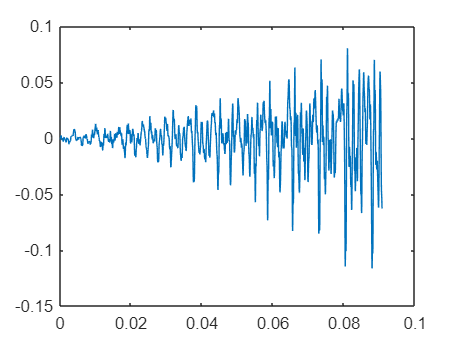

[Y,FS] = audioread("a1.wav");

%%%%% reduzir o tamanho de Y
Y = Y(500:4500);
N = length(Y);
Ts = 1/FS;                            % tempo de amostragem
Tfinal = N*Ts;                        % VALOR FINAL NO TEMPO
t = linspace(0,Tfinal, N);            % gera o vetor tempo

N       = length(Y);               % número de pontos do sinal em análise
Ts      = 1/FS;                     % tempo de amostragem
ws      = 2*pi*FS;                  % frequência anngular
duracao = N*Ts;                     % Duração do sinal
tempo   = linspace(0,duracao,N);       % vetor tempo computacional
fmax    = FS/2;                     % frequência máxima de amostragem

plot(tempo,Y);

sound(Y,FS)